load env
load Agent.mat

## Specifying the Training Parameters and Bellman equation

After we create our environment and initialize agent, we move on to train the agent to find optimal policy. We essentially model the steps an agent takes, and based on it the agent

gets a reward. This script is a detailed explanation of how the Q-values are updated in a Q-table and how we use Bellman equation to do so.

## **Inside a Q-Learning Agent**

Q-learning is an off policy reinforcement learning algorithm that seeks to find the best action to take given the current state. It’s considered off-policy because the q-learning function learns from actions that are outside the current policy, like taking random actions, and therefore a policy isn’t needed. More specifically, q-learning seeks to learn a policy that maximizes the total reward.

The ‘q’ in q-learning stands for quality. Quality in this case represents how useful a given action is in gaining some future reward.

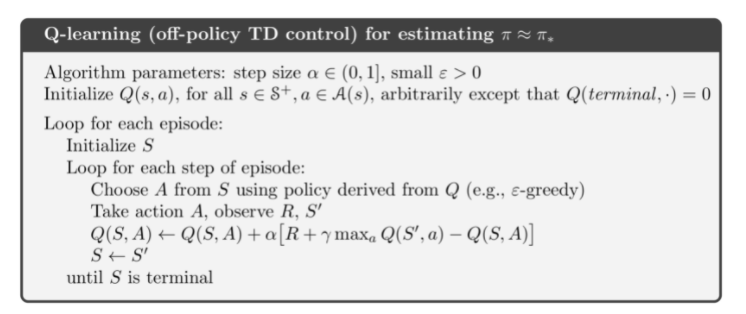

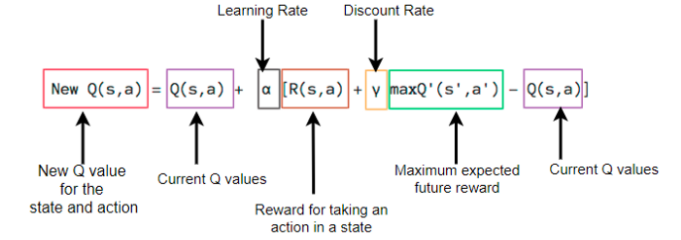

For example:

*Q(s,a) = Q(s,a) + alpha [ R(s,a) + Gamma(maxQ' (s',a')-Q(s,a)]*

*            = 5 + 0.01 [ -1 + 1(5 - 5)]*

*            = 4.9900*

## **Learning rate - **α

A*lpha *or α, can simply be defined as how much you accept the new value vs the old value. Above we are taking the difference between new and old values and then multiplying that difference by the learning rate. This value then gets added to our previous q-value which essentially moves it in the direction of our latest update.

% Agent Parameters
LEARNING_RATE = 0.1;

## **Discount factor - γ**

*γ *is a discount factor. It’s used to balance the immediate and future reward. From our update rule above you can see that we apply the discount to the future reward

DISCOUNT = 0.95;

## **Taking Action: Explore or Exploit**

An agent interacts with the environment in 1 of 2 ways. The first is to use the q-table as a reference and view all possible actions for a given state. The agent then selects the action based on the max value of those actions. This is known as ***exploiting*** since we use the information we have available to us to make a decision.

The second way to take action is to act randomly. This is called ***exploring***. Instead of selecting actions based on the max future reward we select an action at random. Acting randomly is important because it allows the agent to explore and discover new states that otherwise may not be selected during the exploitation process.

You can balance exploration/exploitation using epsilon (*ε*) and setting the value of how often you want to explore vs exploit 

EPSILON = 1;
START_EPSILON_DECAY = 1;
END_EPSILON_DECAY = ceil(EPISODES/2);
decay_rate = EPSILON/(END_EPSILON_DECAY - START_EPSILON_DECAY);

## **Training Parameters**

%Training Parameters
EPISODES = 1;
max_steps_per_episode = 30;
SHOW_EVERY = 1;

% To capture each episode's reward
ep_rewards = [];

% Data to plot graphs

% This will form x-axis - eg: Average reward per episode
aggregate.episodes = [] ;

% To capture trailing average - avg for any given window
aggregate.average = [];

% To capture what's the worst model / reward we have
aggregate.min = [];
aggregate.max = [];

qtable = Agent()

qtable = 8×2 table
    Left    Right
    ____    _____

     5        5  
     5        5  
     5        5  
     5        5  
     5        5  
     5        5  
     5        5  
     5        5  


## **Training Loop**

% This for loop is later converted into a function which can be seen in the
% script Train.mlx

for episodes = 1:EPISODES
    
    % Set episode reward zero at the beginning of each episode
    episode_reward = 0;
    
    fprintf('--------------------------------------');
    fprintf('The Episode number is %d',episodes);
    fprintf('--------------------------------------');
    
    %Reset the environment. In our case this will randomly put the agent in
    %any state.
    state = reset(env);
    
    %done is set to false until the episode ends. Then it is set to True.
    %This is to mark the end of each episode
    done = false;
    
    %while ~done
    % For maximum number of steps in an episode do the following:
    for maxsteps = 1: max_steps_per_episode
        
        fprintf('*************************************');
        fprintf('Step number is %d',maxsteps);
        fprintf('state = %d', state);
        
        %get state, based on it choose an ction using epsillon decay
        %method.

        if rand() > EPSILON
            [max_value, action]= max(qtable{state,:});
        else
            action = randi([1,number_of_actions]);
            max_value = qtable{state,action};
        end

        fprintf('Max Q value for state %d = %.5f',state, max_value);
        fprintf('Which is in coloumn = %d',action);
        
        % Take a step using action choosen and land in a new state
        [new_state,reward,done] = step(env,action);
        
        %Collect reward as per the new state
        episode_reward = episode_reward + reward;
        
        fprintf('new_state = %d', new_state);
        %Update Qvalue using Bellman equation.
        if ~done
            [max_future_q, max_val_ind]= max(qtable{new_state,:});
            
            current_q = qtable{state,action};
            
            fprintf('                                      ');
            fprintf('Old Qvalue for state %d is %.5f',state, current_q);
            
            new_q = (1 - LEARNING_RATE) * current_q + LEARNING_RATE*(reward + DISCOUNT * max_future_q);
            
            fprintf('New Qvalue for state %d is %.5f',state, new_q);
            
            qtable{state,action} = new_q;
            
        elseif new_state == 1 || new_state == 8
            fprintf('                                      ');
            fprintf('Terminal State achieved at episode %d',episodes)
            qtable{state,action} = reward;
        end
        state = new_state;
        
        
    end
    if (END_EPSILON_DECAY >= episodes) && (episodes >= START_EPSILON_DECAY)
        EPSILON = EPSILON - decay_rate;
    end
    %end
    
    ep_rewards = [ ep_rewards, episode_reward]; 
    

    average_reward = sum(ep_rewards(max(end-SHOW_EVERY,1):end)) / numel(ep_rewards(max(end-SHOW_EVERY,1):end));

    aggregate.episodes = [aggregate.episodes, episodes];
    aggregate.average = [aggregate.average, average_reward];
    aggregate.min = [aggregate.min, min(ep_rewards(max(end-SHOW_EVERY,1):end))];
    aggregate.max = [aggregate.max, max(ep_rewards(max(end-SHOW_EVERY,1):end))];

    fprintf("Episode = %d, Average = %d, Min = %d, Max = %d\n", episodes, average_reward, min(ep_rewards(max(end-SHOW_EVERY,1):end)), max(ep_rewards(max(end-SHOW_EVERY,1):end)));

end 

--------------------------------------

The Episode number is 1

--------------------------------------

*************************************

Step number is 1

state = 3

Max Q value for state 3 = 5.00000

Which is in coloumn = 2

new_state = 4

Old Qvalue for state 3 is 5.00000

New Qvalue for state 3 is 4.87500

*************************************

Step number is 2

state = 4

Max Q value for state 4 = 5.00000

Which is in coloumn = 2

new_state = 5

Old Qvalue for state 4 is 5.00000

New Qvalue for state 4 is 4.87500

*************************************

Step number is 3

state = 5

Max Q value for state 5 = 5.00000

Which is in coloumn = 2

new_state = 6

Old Qvalue for state 5 is 5.00000

New Qvalue for state 5 is 4.87500

*************************************

Step number is 4

state = 6

Max Q value for state 6 = 5.00000

Which is in coloumn = 1

new_state = 5

Old Qvalue for state 6 is 5.00000

New Qvalue for state 6 is 4.87500

*************************************

Step number is 5

state = 5

Max Q value for state 5 = 4.87500

Which is in coloumn = 2

new_state = 6

Old Qvalue for state 5 is 4.87500

New Qvalue for state 5 is 4.76250

*************************************

Step number is 6

state = 6

Max Q value for state 6 = 4.87500

Which is in coloumn = 1

new_state = 5

Old Qvalue for state 6 is 4.87500

New Qvalue for state 6 is 4.76250

*************************************

Step number is 7

state = 5

Max Q value for state 5 = 4.76250

Which is in coloumn = 2

new_state = 6

Old Qvalue for state 5 is 4.76250

New Qvalue for state 5 is 4.66125

*************************************

Step number is 8

state = 6

Max Q value for state 6 = 4.76250

Which is in coloumn = 1

new_state = 5

Old Qvalue for state 6 is 4.76250

New Qvalue for state 6 is 4.66125

*************************************

Step number is 9

state = 5

Max Q value for state 5 = 5.00000

Which is in coloumn = 1

new_state = 4

Old Qvalue for state 5 is 5.00000

New Qvalue for state 5 is 4.87500

*************************************

Step number is 10

state = 4

Max Q value for state 4 = 4.87500

Which is in coloumn = 2

new_state = 5

Old Qvalue for state 4 is 4.87500

New Qvalue for state 4 is 4.75063

*************************************

Step number is 11

state = 5

Max Q value for state 5 = 4.66125

Which is in coloumn = 2

new_state = 6

Old Qvalue for state 5 is 4.66125

New Qvalue for state 5 is 4.57012

*************************************

Step number is 12

state = 6

Max Q value for state 6 = 4.66125

Which is in coloumn = 1

new_state = 5

Old Qvalue for state 6 is 4.66125

New Qvalue for state 6 is 4.55825

*************************************

Step number is 13

state = 5

Max Q value for state 5 = 4.87500

Which is in coloumn = 1

new_state = 4

Old Qvalue for state 5 is 4.87500

New Qvalue for state 5 is 4.76250

*************************************

Step number is 14

state = 4

Max Q value for state 4 = 4.75063

Which is in coloumn = 2

new_state = 5

Old Qvalue for state 4 is 4.75063

New Qvalue for state 4 is 4.62800

*************************************

Step number is 15

state = 5

Max Q value for state 5 = 4.76250

Which is in coloumn = 1

new_state = 4

Old Qvalue for state 5 is 4.76250

New Qvalue for state 5 is 4.66125

*************************************

Step number is 16

state = 4

Max Q value for state 4 = 4.62800

Which is in coloumn = 2

new_state = 5

Old Qvalue for state 4 is 4.62800

New Qvalue for state 4 is 4.50802

*************************************

Step number is 17

state = 5

Max Q value for state 5 = 4.66125

Which is in coloumn = 1

new_state = 4

Old Qvalue for state 5 is 4.66125

New Qvalue for state 5 is 4.57012

*************************************

Step number is 18

state = 4

Max Q value for state 4 = 4.50802

Which is in coloumn = 2

new_state = 5

Old Qvalue for state 4 is 4.50802

New Qvalue for state 4 is 4.39138

*************************************

Step number is 19

state = 5

Max Q value for state 5 = 4.57012

Which is in coloumn = 2

new_state = 6

Old Qvalue for state 5 is 4.57012

New Qvalue for state 5 is 4.48811

*************************************

Step number is 20

state = 6

Max Q value for state 6 = 4.55825

Which is in coloumn = 1

new_state = 5

Old Qvalue for state 6 is 4.55825

New Qvalue for state 6 is 4.43659

*************************************

Step number is 21

state = 5

Max Q value for state 5 = 4.57012

Which is in coloumn = 1

new_state = 4

Old Qvalue for state 5 is 4.57012

New Qvalue for state 5 is 4.48811

*************************************

Step number is 22

state = 4

Max Q value for state 4 = 5.00000

Which is in coloumn = 1

new_state = 3

Old Qvalue for state 4 is 5.00000

New Qvalue for state 4 is 4.87500

*************************************

Step number is 23

state = 3

Max Q value for state 3 = 4.87500

Which is in coloumn = 2

new_state = 4

Old Qvalue for state 3 is 4.87500

New Qvalue for state 3 is 4.75063

*************************************

Step number is 24

state = 4

Max Q value for state 4 = 4.87500

Which is in coloumn = 1

new_state = 3

Old Qvalue for state 4 is 4.87500

New Qvalue for state 4 is 4.76250

*************************************

Step number is 25

state = 3

Max Q value for state 3 = 5.00000

Which is in coloumn = 1

new_state = 2

Old Qvalue for state 3 is 5.00000

New Qvalue for state 3 is 4.87500

*************************************

Step number is 26

state = 2

Max Q value for state 2 = 5.00000

Which is in coloumn = 2

new_state = 3

Old Qvalue for state 2 is 5.00000

New Qvalue for state 2 is 4.86313

*************************************

Step number is 27

state = 3

Max Q value for state 3 = 4.87500

Which is in coloumn = 1

new_state = 2

Old Qvalue for state 3 is 4.87500

New Qvalue for state 3 is 4.76250

*************************************

Step number is 28

state = 2

Max Q value for state 2 = 5.00000

Which is in coloumn = 1

new_state = 1

Terminal State achieved at episode 1

*************************************

Step number is 29

state = 1

Max Q value for state 1 = 5.00000

Which is in coloumn = 1

new_state = 1

Terminal State achieved at episode 1

*************************************

Step number is 30

state = 1

Max Q value for state 1 = 0.00000

Which is in coloumn = 1

new_state = 1

Terminal State achieved at episode 1

Episode = 1, Average = -17, Min = -17, Max = -17


- We showed the basic update rule for q-learning.

- We reviewed the required inputs to the algorithm.

- We learned that q-learning uses future rewards to influence the current action given a state and therefore helps the agent select best actions that maximize total reward.

This is the third script of this module. Please [click here](matlab:open('./Training.mlx')) to move on to the next script - `Training.mlx`